# Stochastic gradient descent

In this demo, we will compare classical gradient descent with stochastic gradient descent. For stochastic gradient descent, we choose the batch size to be 1. We'll generate synthetic data and try to estimate the parameters of a straight line, $y=x+1$, i.e., the parameters are $w_0=1$ and $w_1=1$. The estimates will be found by minimizing the residual sum of squares as the measure of how well the model fits the data.

### Data without noise

First we'll generate some data without noise.

global x y
n = 10;
x = (0:1/(n-1):1)';
y = x+1;

Randomly construct an initial guess for $w_0$ and $w_1$ for the optimization procedures. The expected values of the initial guesses are $w_0=1$ and $w_1=1$.

rng(0); % comment this out to try other initial guesses
w0_init = 6*rand-2;
w1_init = 6*rand-2;

The residual sum of squares error function is defined below. Plot contours of this error function for the above data.

clf; fcontour(@E, [-2 4 -2 4],'LevelList',[0:1:30],'MeshDensity',200); hold on

Call gradient descent (GD) and stochastic gradient descent (SGD). These functions, which are defined below, also plot the intermediate solution found after each step. Use 10 epochs and a learning rate (step size) of 0.06 for gradient descent. The equivalent learning rate is used for stochastic gradient descent (which is `n` times larger since we have divided the data into `n` batches).

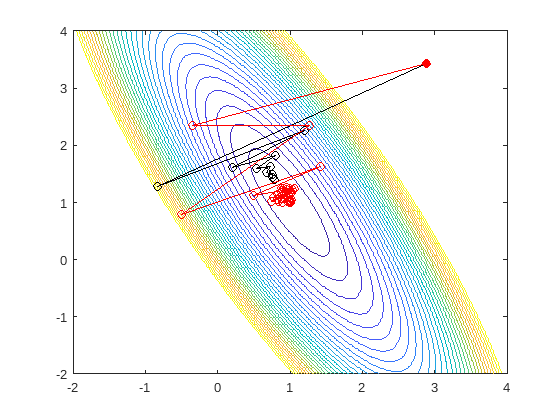

[w0b, w1b] =  gd(w0_init, w1_init, x, y, 10, 0.06);
[w0s, w1s] = sgd(w0_init, w1_init, x, y, 10, 0.06*n, 1.);


fprintf(' GD final error: %e\n', E(w0b,w1b));

 GD final error: 1.628058e-01


fprintf('SGD final error: %e\n', E(w0s,w1s));

SGD final error: 1.189290e-14


GD takes 10 steps (one step for each epoch). SGD takes 100 steps to pass through the 10 epochs. In this example, SGD achieves a much smaller error than GD. We did not have to reduce the learning rate after each epoch in SGD, apparently because there is no noise in the data.

### Data with noise

Now we'll generate `y` values with noise.

y = x+1 + 0.1*randn(size(x));

Draw the contours and plot the results using gradient descent and stochastic gradient descent. The learning rates are the same as in the previous example.

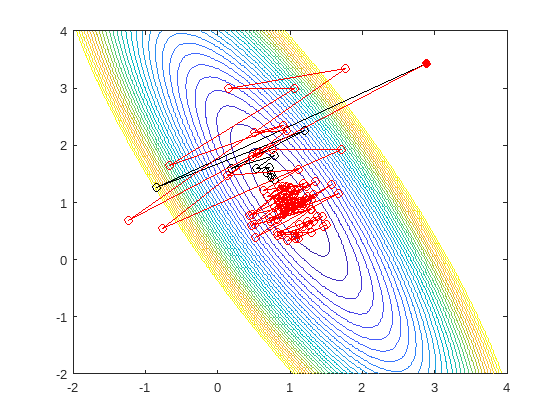

clf; fcontour(@E, [-2 4 -2 4],'LevelList',[0:1:30],'MeshDensity',200); hold on

[w0b, w1b] =  gd(w0_init, w1_init, x, y, 10, 0.06);
[w0s, w1s] = sgd(w0_init, w1_init, x, y, 10, 0.06*n, 1.);


fprintf(' GD final error: %e\n', E(w0b,w1b));

 GD final error: 2.586503e-01


fprintf('SGD final error: %e\n', E(w0s,w1s));

SGD final error: 2.741891e-01


Here we observe that the SGD step sizes remain too large when we are close to the solution. This is because the stochastic gradients do not approach 0 in magnitude as we get closer to the solution.

Now we'll repeat the above experiment, but this time we'll decrease the learning rate in SGD by a factor of 1.5 after every epoch.

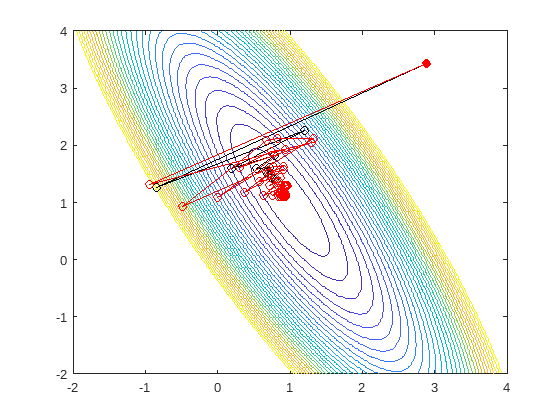

clf; fcontour(@E, [-2 4 -2 4],'LevelList',[0:1:30],'MeshDensity',200); hold on

[w0b, w1b] =  gd(w0_init, w1_init, x, y, 10, 0.06);
[w0s, w1s] = sgd(w0_init, w1_init, x, y, 10, 0.06*n, 1.5);


fprintf(' GD final error: %e\n', E(w0b,w1b));

 GD final error: 2.586503e-01


fprintf('SGD final error: %e\n', E(w0s,w1s));

SGD final error: 1.097839e-01


Now we observe that the SGD error is smaller than when the learning rate was not decreased closer to the solution.

This is the function for gradient descent.  `nepochs` is the number of epochs and `eta` is the learning rate.

function [w0, w1] = gd(w0, w1, x, y, nepochs, eta)
plot(w0, w1, 'o', 'markerfacecolor', 'k'); % plot initial guess
for k = 1:nepochs
  dw0 = sum(2*(w0+w1*x-y));
  dw1 = sum(2*(w0+w1*x-y).*x);
  plot([w0 w0 - eta*dw0],[w1 w1 - eta*dw1],'k-o'); % plot new value
  w0 = w0 - eta*dw0;
  w1 = w1 - eta*dw1;
end
end

This is the stochastic gradient descent function. `etafac` is the factor by which `eta` is reduced after each epoch, e.g., a value of 1.5 will reduce `eta` by 1.5 every epoch.

function [w0, w1] = sgd(w0, w1, x, y, nepochs, eta, etafac)
plot(w0, w1, 'o', 'markerfacecolor', 'r'); % plot initial guess
for k = 1:nepochs
  p = randperm(length(x));
  for j = 1:length(x)
    dw0 = 2*(w0+w1*x(p(j))-y(p(j)));
    dw1 = 2*(w0+w1*x(p(j))-y(p(j))).*x(p(j));
    plot([w0 w0 - eta*dw0],[w1 w1 - eta*dw1],'r-o'); % plot new value
    w0 = w0 - eta*dw0;
    w1 = w1 - eta*dw1;
  end
  eta = eta/etafac;
end
end

This is the residual sum of squares error function, which depends on the entire data set.

function val = E(w0,w1)
global x y
val = 0;
for i = 1:length(x)
  val = val + (w0+w1*x(i)-y(i)).^2;
end
end

### Taking it further

Experiment with the learning rate and the reduction of the learning rate after each epoch in stochastic gradient descent. What values give fast and consistent convergence to the solution, for different initial guesses of the weights?